# Data Averaging

 Ramsey

## Data Input 

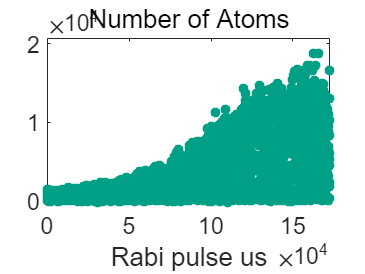

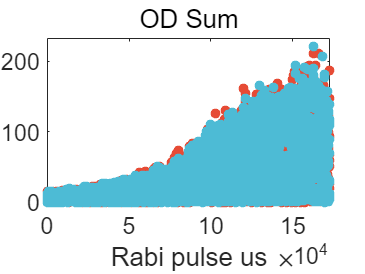

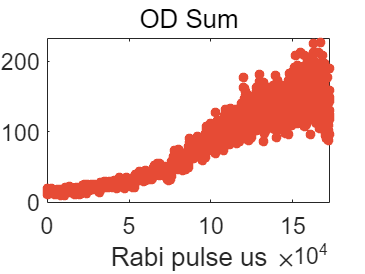

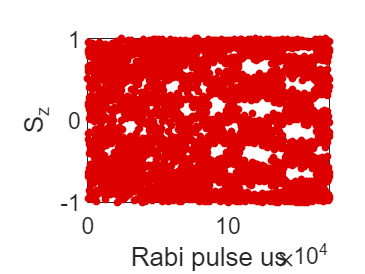

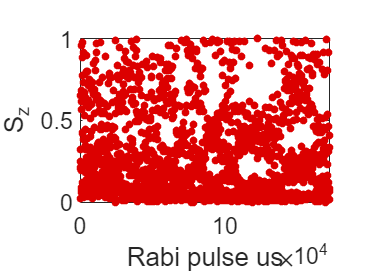

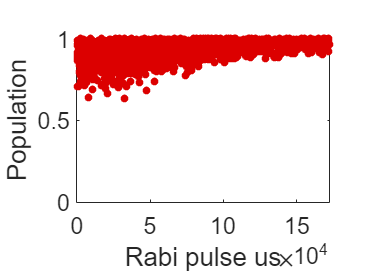

close all
clear all
colors=npg(100); %  basic colors
main_dir='\\Artemis-pc\e\Data\2022-12-24\Abs-3551';
%main_dir='\\Artemis-pc\e\Data\2022-10-04\Abs-3612';
main_dir_0=main_dir;
load([main_dir,'\result.mat']);

clear relativeOD_fit coeff coeffoutput coefferr main_dir


## Reshape data

colors=npg(100);
x_label='Ramsey interrogation time ms';
x_lim_low=0;
x_lim_high=0.250;
y_lim_low=-1.0;
y_lim_high=1.0;

precess_1_list=((0:7:245)+6)/1000; % ms
precess_1_list_plot=(-100:1:1100)/1000;

precess_2_list=fliplr(0:20:180); % s

precess_2_list=(0:20:180); % s
precess_2_list=fliplr([0,1.1:1.1:4.4,8,12,20:20:180]);% s



length_0=length(relativeOD);
length_1=length(precess_1_list);
length_2=length(precess_2_list);

% reshape in row

length_0=length(relativeOD);
length_1=length(precess_1_list);
length_2=length(precess_2_list);

% reshape in row

matrix_1=reshape(relativeOD,length_1,length_0/length_1/length_2,length_2);
matrix_2=reshape(ODsum1+ODsum2,length_1,length_0/length_1/length_2,length_2);
matrix_3=reshape((ODsum1+ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);

matrix_4=reshape((ODsum1)./ODsum3,length_1,length_0/length_1/length_2,length_2);
matrix_5=reshape((ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);

% clear first data run
%matrix_1(:,1:2,:)=[];

matrix_1(:,1,:)=[];

matrix_2(:,1,:)=[];

matrix_3(:,1,:)=[];

matrix_4(:,1,:)=[];
matrix_5(:,1,:)=[];
% clear one strange data point when 'E:\Data\2022-10-04\Abs-3612'
% matrix_1(16,6,5)=mean(matrix_1(16,1:5,5));

%
mean_1=mean(matrix_1,2); % mean in dim 2
std_1=std(matrix_1,0,2); % weight 0, dim 2
weight_1=1./std_1.^2;

mean_2=mean(mean(matrix_2,2),1);
std_2=mean(std(matrix_2,0,2),1);
weight_2=1./std_2.^2;

mean_3=mean(matrix_3,2);
std_3=std(matrix_3,0,2);
weight_3=1./std_3.^2;


mean_4=mean(matrix_4,2);
std_4=std(matrix_4,0,2);
weight_4=1./std_4.^2;

mean_5=mean(matrix_5,2);
std_5=std(matrix_5,0,2);
weight_5=1./std_5.^2;

%  use data in form of (:,:,i)


## Sinusoidal fitting

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.8204  (0.7982, 0.8426)
       b =       12.79  (12.68, 12.91)
       c =      -2.147  (-2.248, -2.045)
       d =     -0.1362  (-0.1598, -0.1127)

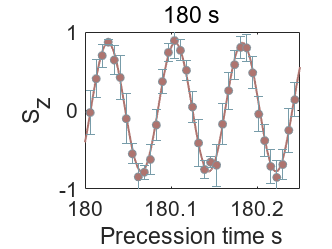

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.8713  (0.8547, 0.8879)
       b =        12.9  (12.85, 12.96)
       c =     -0.5693  (-0.6231, -0.5156)
       d =     -0.1279  (-0.1455, -0.1102)

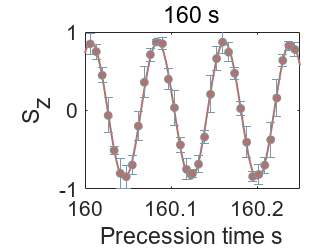

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.8847  (0.8693, 0.9001)
       b =        12.8  (12.75, 12.86)
       c =       1.518  (1.474, 1.562)
       d =     -0.1186  (-0.1389, -0.0983)

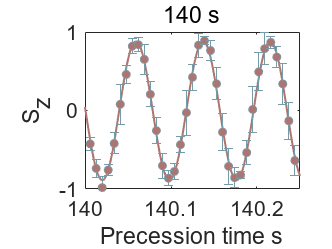

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =       0.924  (0.9109, 0.9371)
       b =       12.84  (12.81, 12.88)
       c =      -2.891  (-2.924, -2.859)
       d =    -0.06576  (-0.08152, -0.04999)

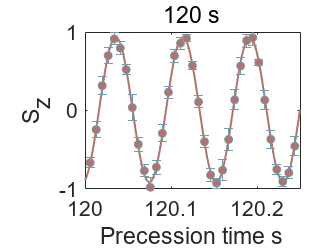

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9214  (0.9111, 0.9318)
       b =       12.83  (12.79, 12.87)
       c =     -0.9554  (-0.9911, -0.9196)
       d =    -0.07566  (-0.08837, -0.06294)

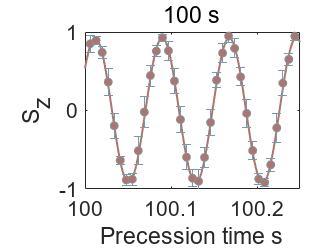

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9399  (0.9311, 0.9487)
       b =       12.83  (12.8, 12.87)
       c =       1.068  (1.037, 1.098)
       d =    -0.06209  (-0.0722, -0.05199)

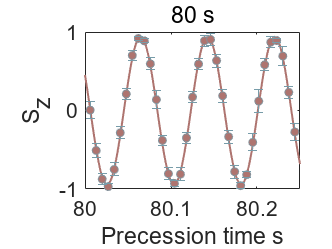

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9469  (0.9372, 0.9567)
       b =       12.81  (12.78, 12.84)
       c =       2.981  (2.955, 3.006)
       d =    -0.04992  (-0.06158, -0.03825)

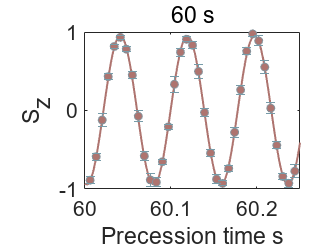

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9559  (0.9461, 0.9657)
       b =       12.86  (12.83, 12.9)
       c =      -1.329  (-1.361, -1.297)
       d =    -0.03853  (-0.05084, -0.02623)

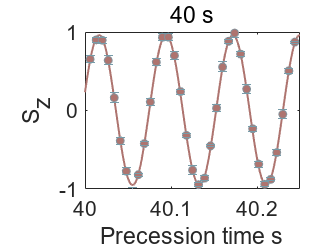

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9657  (0.959, 0.9723)
       b =       12.83  (12.81, 12.84)
       c =      0.7482  (0.7317, 0.7647)
       d =    -0.02912  (-0.03672, -0.02152)

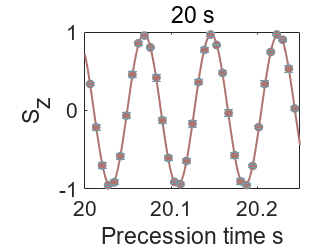

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9735  (0.969, 0.978)
       b =       12.84  (12.83, 12.86)
       c =       2.868  (2.853, 2.882)
       d =     -0.0221  (-0.02612, -0.01809)

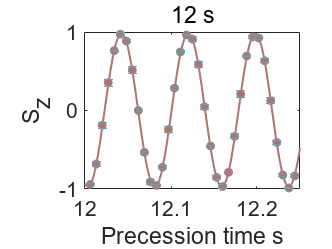

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9812  (0.9748, 0.9876)
       b =       12.83  (12.81, 12.85)
       c =      0.8367  (0.8191, 0.8543)
       d =    -0.01337  (-0.02083, -0.005912)

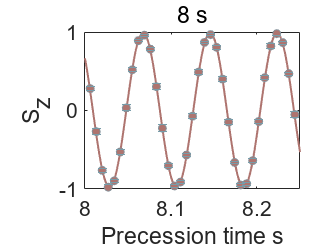

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9817  (0.9747, 0.9888)
       b =        12.8  (12.78, 12.83)
       c =     -0.3003  (-0.324, -0.2766)
       d =    -0.01732  (-0.02468, -0.009958)

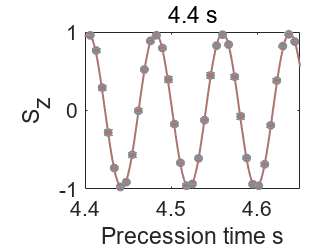

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9858  (0.9801, 0.9916)
       b =       12.84  (12.82, 12.86)
       c =      -1.049  (-1.065, -1.033)
       d =   -0.009847  (-0.01641, -0.003279)

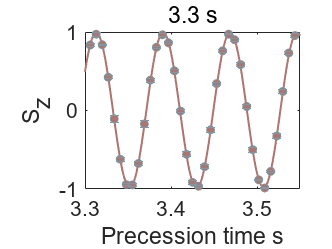

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9819  (0.9772, 0.9867)
       b =       12.83  (12.81, 12.85)
       c =      -1.734  (-1.75, -1.719)
       d =    -0.01359  (-0.01942, -0.007756)

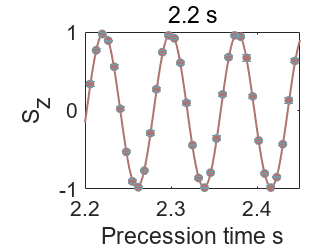

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9884  (0.9834, 0.9935)
       b =       12.83  (12.82, 12.85)
       c =       -2.43  (-2.447, -2.413)
       d =    -0.01082  (-0.01738, -0.004255)

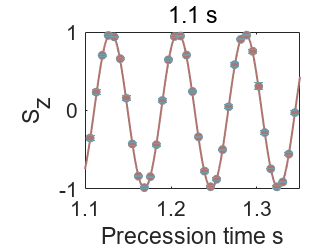

fi =      常规模型:
     fi(x) = a*cos(2*pi*x*b+c)+(1-a)+d
     系数(置信边界为 95%):
       a =      0.9921  (0.987, 0.9972)
       b =       12.84  (12.82, 12.86)
       c =      -3.127  (-3.146, -3.108)
       d =  -3.777e-14  (固定在边界处)

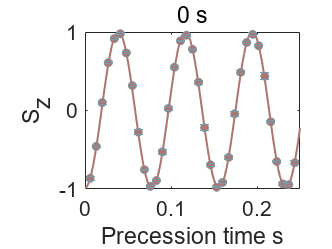

eqn='a*cos(2*pi*x*b+c)+(1-a)+d';
startpoints=[1 12.8 0 0];
lower=[0.1 11 -3.142*1.5 -1];
upper=[1 14 3.142*1.5 0];


% eqn='a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d';
% startpoints=[0.6 0.2 0 0.0128 0 0 0 0];
% lower=[0 0   0 0.01 -3.142*2 -3.142*2 -3.142*2 -1];
% upper=[1 0.5 0.1 0.02 3.142*2 3.142*2  3.142*2 1];

chilist=[];
chilist_reduced=[];

for i = 1:size(mean_1,3)
    %for i=1:1
    fi=fit(precess_1_list',mean_1(:,:,i),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',weight_1(:,:,i));
    fi_result{i}=fi;
    fi
    h=figure;
    plot(precess_1_list_plot+precess_2_list(i),fi(precess_1_list_plot),'LineWidth',1.5,'Color',colors(5,:));
    hold on
    % plot(precess_1_list,mean_1(:,:,i)','.','MarkerSize',15,'Color',colors(8,:));

    I_se=errorbar(precess_1_list+precess_2_list(i),mean_1(:,:,i),std_1(:,:,i),'o');

    title([num2str(precess_2_list(i)),' s']);
    ylim([-1 1]);
    ylabel('S_z');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    ylim([y_lim_low y_lim_high])

    I_se.Color=colors(9,:);
    I_se.MarkerSize=6;
    I_se.MarkerEdgeColor=colors(8,:);
    I_se.MarkerFaceColor=colors(5,:);
    coeffoutput(i,:)=coeffvalues(fi);
    temp = confint(fi);
    coefferr(i,:) = (temp(2,:)-temp(1,:))./4;   %coefferr(:,1) = amplitude, coefferr(:,2) = period 1 sigma error
    clear('temp');
    chilist(i)=sum(((mean_1(:,:,i)-fi(precess_1_list))./std_1(:,:,i)).^2);
    chilist_reduced(i)=chilist(i)/(length(precess_1_list)-4);
    coefferr(i,:).*sqrt(chilist(i));
    saveas(h,[main_dir_0,'\Figure_',num2str(i),'.png'])
    savefig(h,[main_dir_0,'\Figure_',num2str(i),'.fig'])

    [d1,d2] = differentiate(fi_result{1},precess_1_list);
end

## Sindusal fitting two state

ans = -2.1466

ans = 13.5793

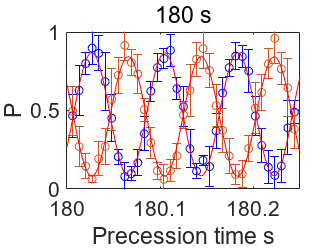

ans = -0.5693

ans = -0.5369

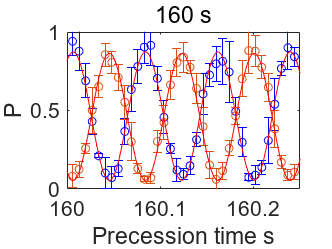

ans = 1.5183

ans = 1.5046

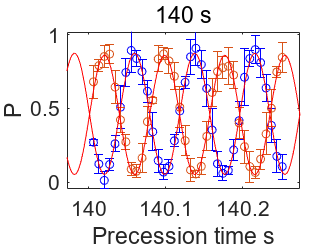

ans = -2.8914

ans = 0.2412

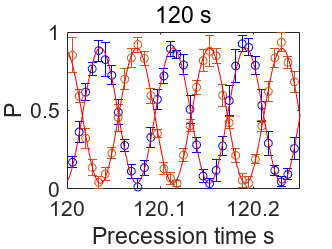

ans = -0.9554

ans = -0.9556

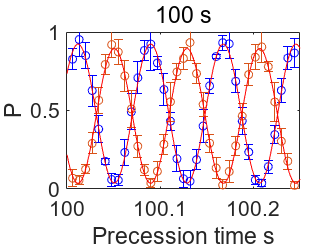

ans = 1.0678

ans = 1.0547

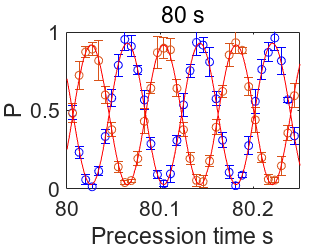

ans = 2.9806

ans = -0.1560

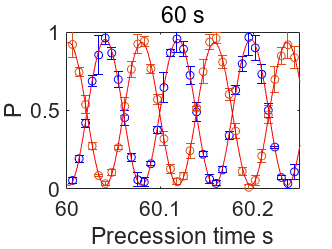

ans = -1.3290

ans = -1.3244

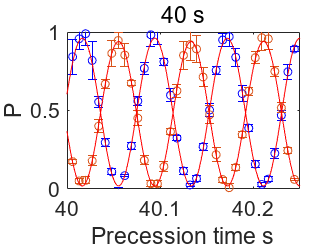

ans = 0.7482

ans = 0.7662

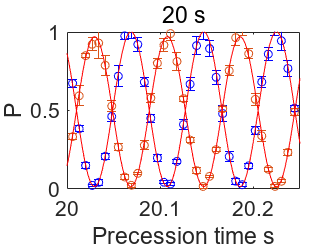

ans = 2.8679

ans = -0.2649

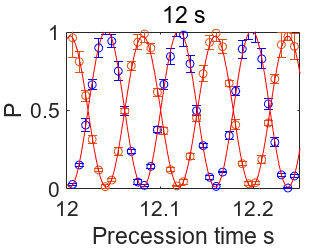

ans = 0.8367

ans = 0.8369

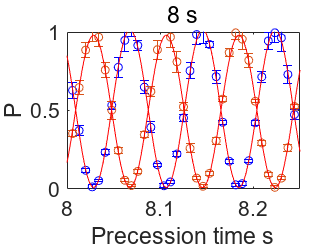

ans = -0.3003

ans = -0.3318

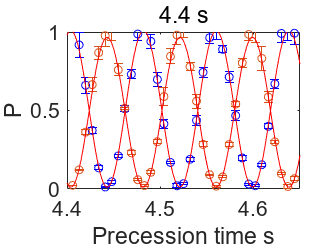

ans = -1.0492

ans = -1.0429

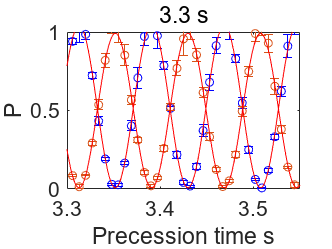

ans = -1.7345

ans = 4.5479

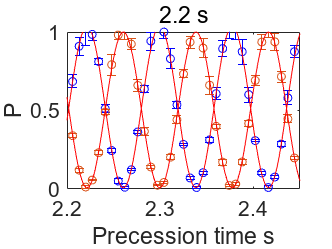

ans = -2.4298

ans = 0.7182

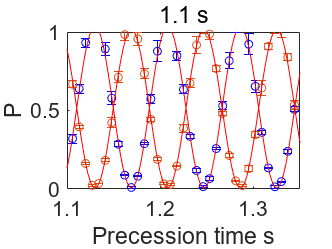

ans = -3.1269

ans = 0.0209

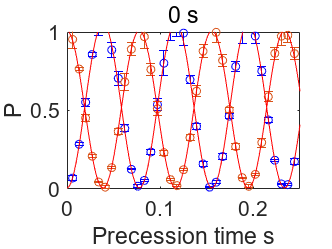

eqn='a*sin(2*pi*x*b+c)+(1-a)+d';
startpoints=[1 12.8 0 0];
lower=[0.1 11 -3.142*1.5 -1];
upper=[1 14 3.142*1.5 0];

chilist=[];
chilist_reduced=[];

[p_1,p_2,contrast,freq,phase_1]=deal(zeros(1,size(mean_1,3)));
[p_1_err,p_2_err,contrast_err,freq_err,phase_1_err]=deal(zeros(1,size(mean_1,3)));


for i = 1:size(mean_1,3)
    fi=fi_result{i};
    fi.c

    %for i=1:1
    x_cell={precess_1_list,precess_1_list};
    y_cell={transpose(mean_4(:,:,i)),transpose(mean_5(:,:,i))};
    w_cell={transpose(weight_4(:,:,i)),transpose(weight_5(:,:,i))};
    mdl1 = @(beta,x) beta(1)/2*(1+beta(3)*cos(2*pi*beta(4)*x+beta(5)));
    mdl2 = @(beta,x) beta(2)/2*(1-beta(3)*cos(2*pi*beta(4)*x+beta(5)));
    mdl_cell = {mdl1, mdl2};
    beta0=[1 1 1 12.8 0];
    [beta,r,J,Sigma,mse,errorparam,robustw] = nlinmultifit(x_cell, y_cell, mdl_cell, beta0,'weights',w_cell);
    % Calculate model predictions and confidence intervals
    [ypred1,delta1] = nlpredci(mdl1,precess_1_list_plot,beta,r,'covar',Sigma);
    [ypred2,delta2] = nlpredci(mdl2,precess_1_list_plot,beta,r,'covar',Sigma);
    beta(5)
    % Calculate parameter confidence intervals
    ci = nlparci(beta,r,'Jacobian',J);

    fig_p2=figure;
    hold all;
    box on;
    %scatter(precess_1_list+precess_2_list(i),transpose(mean_4(:,:,i)));
    %scatter(precess_1_list+precess_2_list(i),transpose(mean_5(:,:,i)));
    errorbar(precess_1_list+precess_2_list(i),mean_4(:,:,i),std_4(:,:,i),'o','Color','blue');
    errorbar(precess_1_list+precess_2_list(i),mean_5(:,:,i),std_5(:,:,i),'o');
    plot(precess_1_list_plot+precess_2_list(i),ypred1,'Color','red');
    plot(precess_1_list_plot+precess_2_list(i),ypred2,'Color','red');

    title([num2str(precess_2_list(i)),' s']);
    ylim([0 1]);
    ylabel('P');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    ylim([0 y_lim_high])


    p_1(i)=beta(1);
    p_2(i)=beta(2);
    contrast(i)=abs(beta(3));
    freq(i)=beta(4);
    phase_1(i)=beta(5);

    beta_err=(ci(6:10)-ci(1:5))./4;
    p_1_err(i)=beta_err(1);
    p_2_err(i)=beta_err(2);
    contrast_err(i)=beta_err(3);
    freq_err(i)=beta_err(4);
    phase_1_err(i)=beta_err(5);

    saveas(fig_p2,[main_dir_0,'\Figure_p2_',num2str(i),'.png'])
    savefig(fig_p2,[main_dir_0,'\Figure_p2_',num2str(i),'.fig'])

end

## Plot contrast decay - two

f_contrast_decay=figure;

eqn='a*exp(-x/b)';
startpoints=[1 1000];
lower=[0.8 -1];
upper=[1 10000];
fi=fit(precess_2_list',contrast',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_err.^2);
fi

fi =      常规模型:
     fi(x) = a*exp(-x/b)
     系数(置信边界为 95%):
       a =      0.9852  (0.9825, 0.988)
       b =        1478  (1274, 1682)

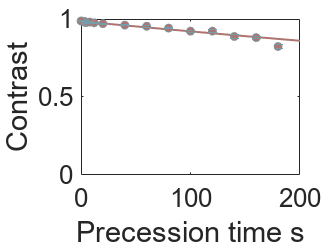

plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on
hold all
h1=errorbar(precess_2_list',contrast,contrast_err,'o');
hold on;
%h1=errorbar(precess_2_list',coeffoutput(:,1),coefferr(:,1),'o');
ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
h1.Color=colors(9,:);
h1.MarkerSize=6;
h1.MarkerEdgeColor=colors(8,:);
h1.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')
ylim([0 1])

savefig(f_contrast_decay,[main_dir_0,'\ContrastDecay.fig'])
saveas(f_contrast_decay,[main_dir_0,'\ContrastDecay.png'])

## Plot population decay - two

f_population_decay=figure;
hold all
h1=errorbar(precess_2_list',p_1,p_1_err,'o');
h2=errorbar(precess_2_list',p_2,p_2_err,'o');

% eqn='(1-c)*exp(-(x/b)^1)+c+0*a';
% startpoints=[10000 100 0.5 ];
% lower=[0 0 0.5];
% upper=[1000000 10000 0.6];

eqn='a*exp(-x^1/b^1)+c';
startpoints=[0.5 1 1];
lower=[0 0 0];
upper=[1.1 2000000 1];


fi_pop_coherent=fit(precess_2_list',p_1',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_1_err.^2);
fi_pop_coherent_p1=fi_pop_coherent

fi_pop_coherent_p1 =      常规模型:
     fi_pop_coherent_p1(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =      0.1143  (0.0938, 0.1348)
       b =       50.45  (24.43, 76.47)
       c =      0.9344  (0.9125, 0.9562)

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

fi_pop_coherent=fit(precess_2_list',p_2',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_2_err.^2);
fi_pop_coherent_p2=fi_pop_coherent

fi_pop_coherent_p2 =      常规模型:
     fi_pop_coherent_p2(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =     0.09179  (0.06425, 0.1193)
       b =       62.37  (15.19, 109.5)
       c =      0.9148  (0.8849, 0.9447)

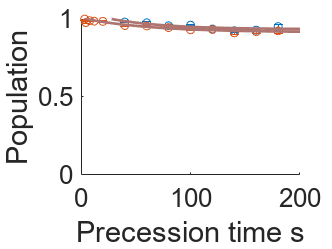

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')

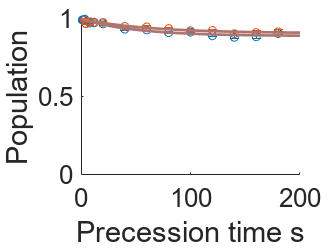



figure
hold all
h1=errorbar(precess_2_list',p_1./(fi_pop_coherent_p1.a+fi_pop_coherent_p1.c),p_1_err./(fi_pop_coherent_p1.a+fi_pop_coherent_p1.c),'o');
h2=errorbar(precess_2_list',p_2./(fi_pop_coherent_p2.a+fi_pop_coherent_p2.c),p_2_err./(fi_pop_coherent_p2.a+fi_pop_coherent_p2.c),'o');
plot((0:1:200),fi_pop_coherent_p1(0:1:200)./(fi_pop_coherent_p1.a+fi_pop_coherent_p1.c),'LineWidth',2,'Color',colors(5,:));
plot((0:1:200),fi_pop_coherent_p2(0:1:200)./(fi_pop_coherent_p2.a+fi_pop_coherent_p2.c),'LineWidth',2,'Color',colors(5,:));
ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')


f_pop_decay=figure;
hold all
fi_pop_coherent=fit(precess_2_list',(p_1+p_2)'./2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_1_err.^2+1./p_2_err.^2);
fi_pop_coherent_p1_p2=fi_pop_coherent

fi_pop_coherent_p1_p2 =      常规模型:
     fi_pop_coherent_p1_p2(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =      0.1039  (0.08348, 0.1243)
       b =       56.55  (26.71, 86.38)
       c =      0.9234  (0.9013, 0.9454)

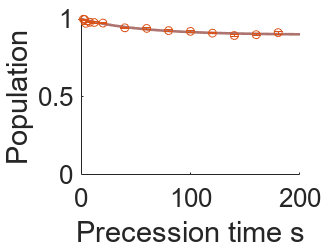

plot((0:1:200),fi_pop_coherent(0:1:200)./(fi_pop_coherent_p1_p2.a+fi_pop_coherent_p1_p2.c),'LineWidth',2,'Color',colors(5,:));

h1=errorbar(precess_2_list',(p_1+p_2)./2./(fi_pop_coherent_p1_p2.a+fi_pop_coherent_p1_p2.c),sqrt(p_1_err.^2+p_2_err.^2)/2./(fi_pop_coherent_p1_p2.a+fi_pop_coherent_p1_p2.c),'o');
ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')
p_average=(p_1+p_2)./2./(fi_pop_coherent_p1_p2.a+fi_pop_coherent_p1_p2.c);
p_average_err=sqrt(p_1_err.^2+p_2_err.^2)/2./(fi_pop_coherent_p1_p2.a+fi_pop_coherent_p1_p2.c);

savefig(f_pop_decay,[main_dir_0,'\PopulationDecay.fig'])
saveas(f_pop_decay,[main_dir_0,'\Populationdecay.png'])

## Plot contrast decay

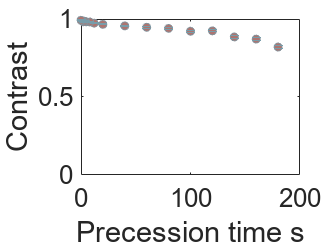


% amplitude
figure;
h1=errorbar(precess_2_list',coeffoutput(:,1),coefferr(:,1),'o');
hold on;
%h1=errorbar(precess_2_list',coeffoutput(:,1),coefferr(:,1),'o');
ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
h1.Color=colors(9,:);
h1.MarkerSize=6;
h1.MarkerEdgeColor=colors(8,:);
h1.MarkerFaceColor=colors(5,:);
set(gca,'YScale','linear')
ylim([0 1])

% period
figure;
h2=errorbar(precess_2_list',coeffoutput(:,2),coefferr(:,2),'.','CapSize',1,'LineWidth',1.5,'MarkerSize',15,'Color','#0072BD');
hold on
%h2=errorbar(precess_2_list',coeffoutput(:,2),coefferr(:,2),'.','CapSize',1,'LineWidth',1.5,'MarkerSize',15);
ylabel('Period ms');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])

saveas(h1,[main_dir_0,'\Contrast.png'])

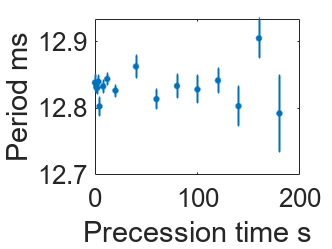

saveas(h2,[main_dir_0,'\Period.png'])

## Plot population decay

h_p =   Figure (58) - 属性:

      Number: 58
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


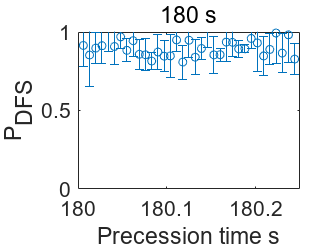

h_p =   Figure (59) - 属性:

      Number: 59
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


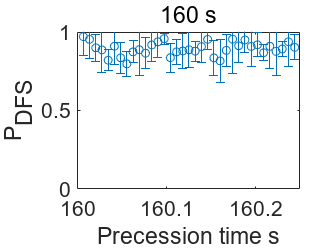

h_p =   Figure (60) - 属性:

      Number: 60
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


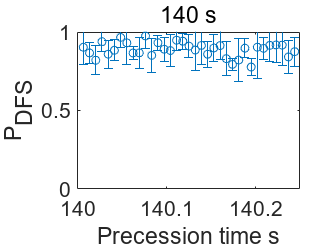

h_p =   Figure (61) - 属性:

      Number: 61
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


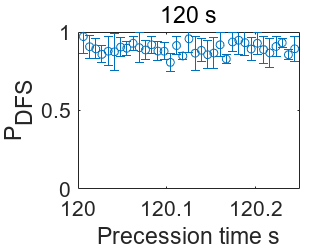

h_p =   Figure (62) - 属性:

      Number: 62
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


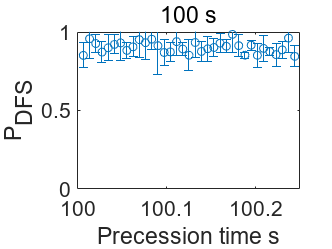

h_p =   Figure (63) - 属性:

      Number: 63
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


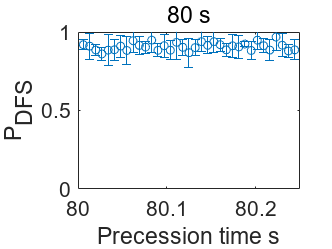

h_p =   Figure (64) - 属性:

      Number: 64
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


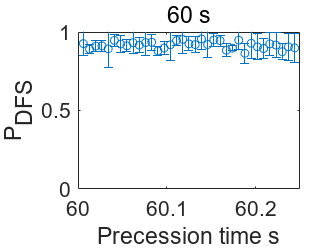

h_p =   Figure (65) - 属性:

      Number: 65
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


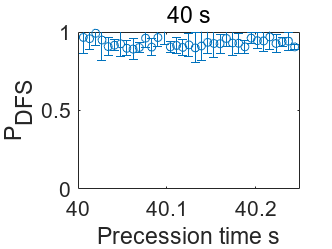

h_p =   Figure (66) - 属性:

      Number: 66
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


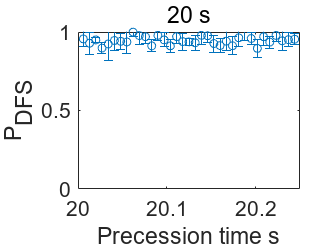

h_p =   Figure (67) - 属性:

      Number: 67
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


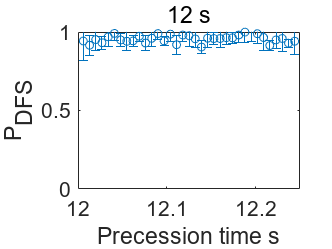

h_p =   Figure (68) - 属性:

      Number: 68
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


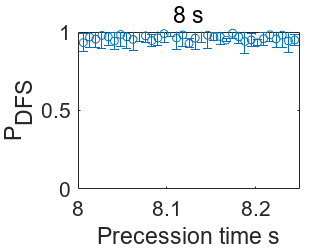

h_p =   Figure (69) - 属性:

      Number: 69
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


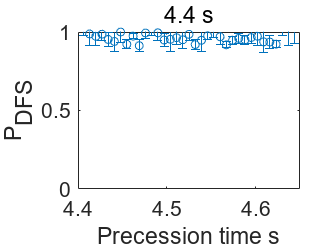

h_p =   Figure (70) - 属性:

      Number: 70
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


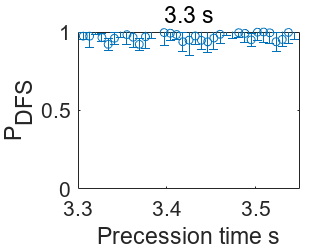

h_p =   Figure (71) - 属性:

      Number: 71
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


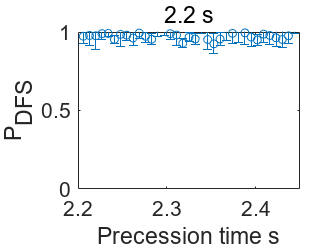

h_p =   Figure (72) - 属性:

      Number: 72
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


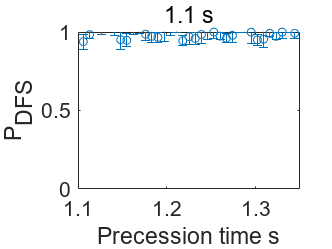

h_p =   Figure (73) - 属性:

      Number: 73
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


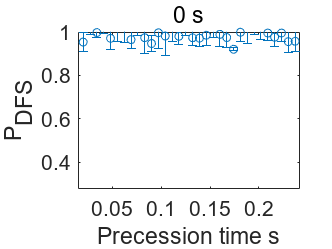

loss_factor=0.95;
for i = 1:size(mean_1,3)
    h_p=figure
    I_se=errorbar(precess_1_list+precess_2_list(i),loss_factor*mean_3(:,:,i),loss_factor*std_3(:,:,i),'o');
    title([num2str(precess_2_list(i)),' s']);
    ylim([0 1]);
    ylabel('P_{DFS}');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    saveas(h_p,[main_dir_0,'\Figure_p_',num2str(i),'.png'])
    savefig(h_p,[main_dir_0,'\Figure_p_',num2str(i),'.fig'])
end

precess_12_list=reshape(precess_2_list+precess_1_list',[],1);
mean_3_reshape_1=reshape(mean_3,[],1);
f_pop_h_pop=errorbar(precess_12_list,reshape(mean_3,[],1),reshape(std_3,[],1),'o')

f_pop_h_pop =   ErrorBar - 属性:

             Color: [0 0.4470 0.7410]
         LineStyle: 'none'
         LineWidth: 0.5000
            Marker: 'o'
             XData: [180.0060 180.0130 180.0200 180.0270 180.0340 180.0410 180.0480 180.0550 180.0620 180.0690 180.0760 180.0830 180.0900 180.0970 180.1040 180.1110 180.1180 180.1250 180.1320 180.1390 180.1460 180.1530 180.1600 180.1670 180.1740 … ]
             YData: [0.9622 0.8984 0.9446 0.9608 1.0568 0.9553 1.0201 0.9299 0.9942 0.9032 0.8998 0.8578 0.9184 0.8904 0.8922 0.9995 0.8509 0.9974 0.8837 0.9419 1.0773 0.8991 0.9003 0.9851 0.9834 0.9391 0.9400 1.0095 0.9793 0.8922 0.9359 1.0458 … ]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.1429 0.2080 0.1023 0.1226 0.1342 0.1183 0.0794 0.0777 0.1045 0.1011 0.1069 0.0551 0.1183 0.1019 0.1458 0.0782 0.1138 0.1159 0.1179 0.0763 0.1276 0.1261 0.0443 0.1296 0

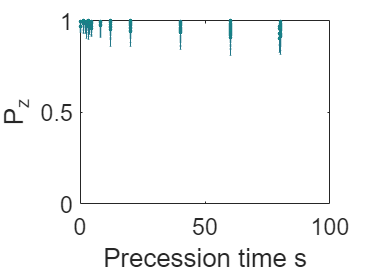


f_pop_h_pop.CapSize=1;
f_pop_h_pop.Color=colors(29,:);
f_pop_h_pop.MarkerSize=2;
f_pop_h_pop.MarkerEdgeColor=colors(28,:);
f_pop_h_pop.MarkerFaceColor=colors(25,:);

ylim([0 1]);
ylabel('P_z');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 100])


figure


f_pop_h_pop=errorbar(precess_12_list,reshape(mean_3,[],1),reshape(std_3,[],1),'o')

f_pop_h_pop =   ErrorBar - 属性:

             Color: [0 0.4470 0.7410]
         LineStyle: 'none'
         LineWidth: 0.5000
            Marker: 'o'
             XData: [180.0060 180.0130 180.0200 180.0270 180.0340 180.0410 180.0480 180.0550 180.0620 180.0690 180.0760 180.0830 180.0900 180.0970 180.1040 180.1110 180.1180 180.1250 180.1320 180.1390 180.1460 180.1530 180.1600 180.1670 180.1740 … ]
             YData: [0.9622 0.8984 0.9446 0.9608 1.0568 0.9553 1.0201 0.9299 0.9942 0.9032 0.8998 0.8578 0.9184 0.8904 0.8922 0.9995 0.8509 0.9974 0.8837 0.9419 1.0773 0.8991 0.9003 0.9851 0.9834 0.9391 0.9400 1.0095 0.9793 0.8922 0.9359 1.0458 … ]
    XNegativeDelta: [1×0 double]
    XPositiveDelta: [1×0 double]
    YNegativeDelta: [0.1429 0.2080 0.1023 0.1226 0.1342 0.1183 0.0794 0.0777 0.1045 0.1011 0.1069 0.0551 0.1183 0.1019 0.1458 0.0782 0.1138 0.1159 0.1179 0.0763 0.1276 0.1261 0.0443 0.1296 0

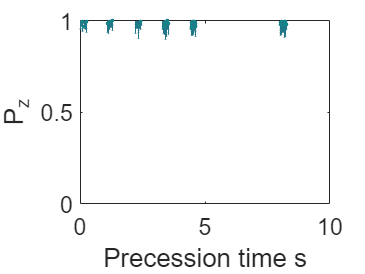


f_pop_h_pop.CapSize=1;
f_pop_h_pop.Color=colors(29,:);
f_pop_h_pop.MarkerSize=2;
f_pop_h_pop.MarkerEdgeColor=colors(28,:);
f_pop_h_pop.MarkerFaceColor=colors(25,:);

ylim([0 1]);
ylabel('P_z');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 10])

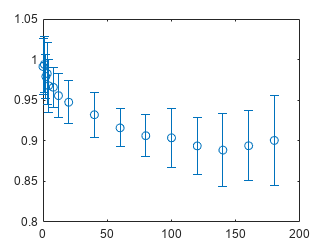




mean_3_mean=squeeze(mean(mean_3))*loss_factor;
mean_3_mean_std=squeeze(std(mean_3))*loss_factor;
mean_3_mean_weight=squeeze(1./mean_3_mean_std.^2);


errorbar(precess_2_list,mean_3_mean,mean_3_mean_std,'o')




% population decay-fitting


eqn='(1-c)*exp(-(x/b)^1)+c';
startpoints=[10000 1];
lower=[0 0];
upper=[1000000 1];

% eqn='a*exp(-x^1/b^1)+(1-a)';
% startpoints=[0.5 1];
% lower=[0 0 ];
% upper=[1 200];


fi_pop_coherent=fit(precess_2_list',mean_3_mean,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',mean_3_mean_weight);
fi_pop_coherent.b

ans = 23.9345

coef_bound=confint(fi_pop_coherent);
(coef_bound(2,:)-coef_bound(1,:))/4

ans =     3.8043    0.0047


chi_fit=sum((((fi_pop_coherent(precess_2_list))-mean_3_mean)./mean_3_mean_std).^2)

chi_fit = 1.0809


chi_fit_reduced=chi_fit/(length(precess_2_list))

chi_fit_reduced = 0.0676



fi_pop_coherent

fi_pop_coherent =      常规模型:
     fi_pop_coherent(x) = (1-c)*exp(-(x/b)^1)+c
     系数(置信边界为 95%):
       b =       23.93  (16.33, 31.54)
       c =      0.9016  (0.8922, 0.911)

f_pop_decay=figure

f_pop_decay =   Figure (75) - 属性:

      Number: 75
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


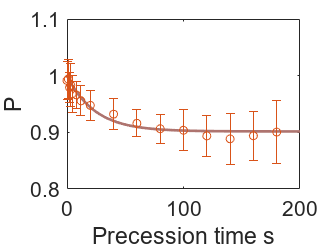

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));

hold on

errorbar(precess_2_list,mean_3_mean,mean_3_mean_std,'o')
ylim([0.8 1.1]);
ylabel('P');
xlabel('Precession time s');
set(gca,'FontSize',16);
xlim([x_lim_low 200])

%set(gca,'YScale','log')

% savefig(f_pop_decay,[main_dir_0,'\PopulationDecay.fig'])
% saveas(f_pop_decay,[main_dir_0,'\Population decay.png'])


## Plot differential & sensitivity

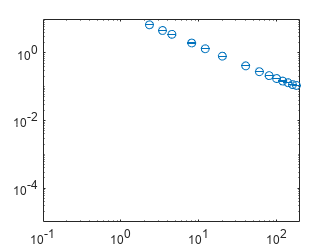

slope_max=zeros(1,size(mean_1,3));
slope_min=zeros(1,size(mean_1,3));

for i = 1:size(mean_1,3)
    [d1] = differentiate(fi_result{i},precess_1_list_plot);
    slope_max(i)=max(d1);
    slope_min(i)=-min(d1);
end

amp_list=contrast';
amp_error=contrast_err';


g_I=0.27102;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;

%slope_max_error=sqrt(slope_max.^2*())
precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);

% sensitivity=1./precess_2_list_sensitivity./slope_max*12.5*100./((mean_3_mean).^0.5)';
% sensitivity_error=(amp_error./amp_list)'.*sensitivity./((mean_3_mean).^0.5)';

sensitivity=1./precess_2_list_sensitivity./amp_list'./((p_average).^0.5)/gyro_factor*10^9/5;
sensitivity_error=((amp_error./amp_list)'+0.5*(p_average_err./p_average)).*sensitivity;

sensitivity_decay=figure;
%scatter(precess_2_list_sensitivity,sensitivity)
%hold on
errorbar(precess_2_list_sensitivity,sensitivity,sensitivity_error,'o')
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
ylim([1e-5 10])
box on

hold on


savefig(sensitivity_decay,[main_dir_0,'\SensitivityDecay.fig'])

## Vacuum decay

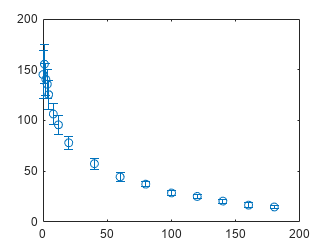

% number decay

n_list=squeeze(mean_2(:,:,:));
n_std=squeeze(std_2(:,:,:));
[n_max,n_max_index]=max(n_list);
n_fit_weight=1./n_std.^2;

n_norm=n_list./n_max;
n_std_norm=n_std./n_max;

figure;
errorbar(precess_2_list(1:end)',n_list,n_std,'o')


eqn='exp(-x/a)*b';
startpoints=[50 1];
lower=[20 0];
upper=[100 1];

fi=fit(precess_2_list(1:end)',n_norm(1:end),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',n_fit_weight(1:end));
f_vacuum_decay=figure;
plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

chi_fit=sum(((fi(precess_2_list)-n_norm(1:end))./n_std_norm).^2)

chi_fit = 34.2427


chi_fit_reduced=chi_fit/(length(precess_2_list)-2)

chi_fit_reduced = 2.4459


fi.a

ans = 78.5356

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     5.2091    0.0481


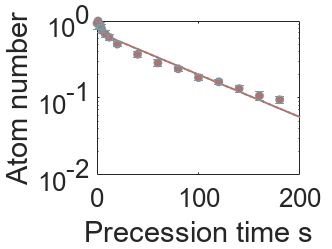


h3=errorbar(precess_2_list',n_norm,n_std_norm,'o');


ylabel('Atom number');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
h3.Color=colors(9,:);
h4.MarkerSize=6;
h3.MarkerEdgeColor=colors(8,:);
h3.MarkerFaceColor=colors(5,:);
set(gca,'YScale','log')
ylim([0.01 1])
saveas(f_vacuum_decay,[main_dir_0,'\Vacuum decay.png'])

## Magnetic field

figure;
h2=errorbar(precess_2_list',coeffoutput(:,2),coefferr(:,2),'.','CapSize',1,'LineWidth',1.5,'MarkerSize',15,'Color','#0072BD');
hold on
%h2=errorbar(precess_2_list',coeffoutput(:,2),coefferr(:,2),'.','CapSize',1,'LineWidth',1.5,'MarkerSize',15);
ylabel('Period ms');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])

f_mean=coeffoutput(:,2);
f_mean_weight=1./coefferr(:,2);

[xData, yData, weights] = prepareCurveData( precess_2_list, f_mean', f_mean_weight' );

% 设置 fittype 和选项。
ft = fittype( 'a*x^0', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.0357116785741896;
opts.Weights = weights;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

B_mean=2*pi*fitresult.a/gyro_factor/5*10^9 %nT

B_mean = 1.2424e+03


aaa=confint(fitresult);
B_error=(aaa(2)-aaa(1))/4/fitresult.a

B_error = 3.9240e-04

## Fitting

% amp_list=coeffoutput(:,1);
% amp_error=coefferr(:,1);
% 
% chilist_reduced(chilist_reduced<1)=1; % reduced chi square < 1, take value as 1
% amp_error=coefferr(:,1).*sqrt(chilist_reduced');
% 
% amp_weight=1./amp_error.^2;
% 
% eqn='a*exp(-x*b)';
% startpoints=[1 0];
% lower=[0.8 -1];
% upper=[1 1];
% 
% fi=fit(precess_2_list',amp_list,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',amp_weight);
% f_amp_decay=figure;
% plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
% hold on
% 
% chi_fit=sum(((fi(precess_2_list)-amp_list)./amp_error).^2)
% 
% chi_fit_reduced=chi_fit/(length(precess_2_list)-2)
% 
% hold on
% 
% fi.a
% fi.b
% confint(fi)
% temp = confint(fi);
% (temp(2,:)-temp(1,:))/4*1e4
% 
% 1/fi.b
% (1/temp(3)-1/temp(4))/4
% (1/temp(3)-1/temp(4))/4*sqrt(chi_fit_reduced)
% 
% h3=errorbar(precess_2_list',amp_list,amp_error,'o');
% 
% 
% ylabel('Contrast');
% xlabel('Precession time s');
% set(gca,'FontSize',20);
% xlim([0 200])
% h3.Color=colors(9,:);
% h4.MarkerSize=6;
% h3.MarkerEdgeColor=colors(8,:);
% h3.MarkerFaceColor=colors(5,:);
% set(gca,'YScale','linear')
% ylim([0 1])
% 
% savefig(f_amp_decay,[main_dir_0,'\AmpDecay.fig'])
% saveas(f_amp_decay,[main_dir_0,'\Contrast decay.png'])


## Save result

save([main_dir_0,'\average.mat'])